clear all

characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];

Mapset = cell(32,2);

for i = 1:length(characters)
    Mapset{i,1} = characters(i);
    Mapset{i,2} = dec2bin(i-1,5); 
end
Mapset

Mapset = 32×2 cell array
    {'a'}    {'00000'}
    {'b'}    {'00001'}
    {'c'}    {'00010'}
    {'d'}    {'00011'}
    {'e'}    {'00100'}
    {'f'}    {'00101'}
    {'g'}    {'00110'}
    {'h'}    {'00111'}
    {'i'}    {'01000'}
    {'j'}    {'01001'}
    {'k'}    {'01010'}
    {'l'}    {'01011'}
    {'m'}    {'01100'}
    {'n'}    {'01101'}
    {'o'}    {'01110'}
    {'p'}    {'01111'}
    {'q'}    {'10000'}
    {'r'}    {'10001'}
    {'s'}    {'10010'}
    {'t'}    {'10011'}
    {'u'}    {'10100'}
    {'v'}    {'10101'}
    {'w'}    {'10110'}
    {'x'}    {'10111'}
    {'y'}    {'11000'}
    {'z'}    {'11001'}
    {' '}    {'11010'}
    {'.'}    {'11011'}
    {','}    {'11100'}
    {'!'}    {'11101'}


bit_rate = 3;
bits_Mapset = cell(2^bit_rate, 1);

for i = 1:2^bit_rate
    bits_Mapset{i} = dec2bin(i - 1, bit_rate);
end

bits_Mapset

bits_Mapset = 8×1 cell array
    {'000'}
    {'001'}
    {'010'}
    {'011'}
    {'100'}
    {'101'}
    {'110'}
    {'111'}



function thresholds = get_thresholds(bit_rate)
    threshold = 1 / (2 * (2^bit_rate - 1));
    thresholds = zeros(1, 2^bit_rate - 1);
    for i = 1:(2^bit_rate)
        thresholds(i) = (i * 2 - 1) * threshold;
    end
end

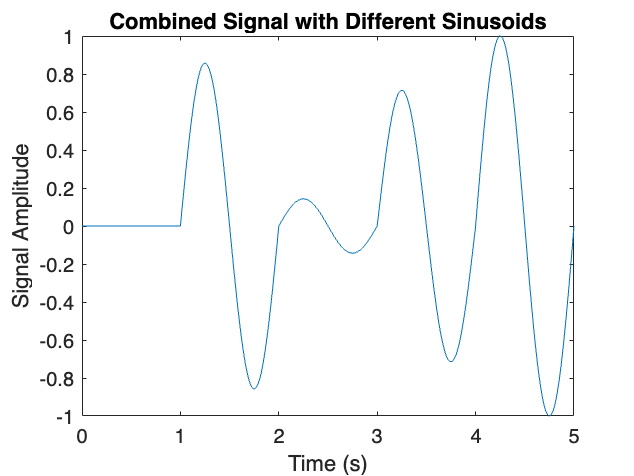

bit_rate = 3;  % Example bit_rate
thresholds = get_thresholds(bit_rate);

% Initialize time vector and signal
t = 0:0.01:1;
signal = (0/(2^bit_rate - 1)) * sin(2 * pi * t);

% Create time vector and concatenate signals for each time segment
t1 = 1:0.01:2;
signal = [signal, (6/(2^bit_rate - 1)) * sin(2 * pi * t1)];

t2 = 2:0.01:3;
signal = [signal, (1/(2^bit_rate - 1)) * sin(2 * pi * t2)];

t3 = 3:0.01:4;
signal = [signal, (5/(2^bit_rate - 1)) * sin(2 * pi * t3)];

t4 = 4:0.01:5;
signal = [signal, (7/(2^bit_rate - 1)) * sin(2 * pi * t4)];

% Combine time vectors for the final plot
time = [t, t1, t2, t3, t4];

% Plot the final signal
figure;
plot(time, signal);
xlabel('Time (s)');
ylabel('Signal Amplitude');
title('Combined Signal with Different Sinusoids');

% t = 0:0.01:1;
% compare_signal = 2 * sin(2 * pi * t);
% result = xcorr(compare_signal, signal);
% figure
% plot(result, [t,t[1:t-1]]);
t = 0:0.01:1;
compare_signal = 2 * sin(2 * pi * t);
result = 0.01 * xcorr(compare_signal, signal);

% Create a time vector for the cross-correlation result
% t_result = -fliplr(t(2:end));  % Time shift for negative part of xcorr
% t_result = [t_result, t];      % Combine for the full range
% 
% % Plot the cross-correlation
% figure;
% plot(t_result, result);
% xlabel('Time (s)');
% ylabel('Cross-correlation');
% title('Cross-correlation between signals');



% Initialize the result and bits array
bits = [];
segment_length = 101;  % Divide signal into 5 segments

% Iterate over each second (5 segments)
for i = 1:(length(signal)/101)
    % Extract the corresponding segment of the signal for each second
    segment_start = round((i-1) * segment_length) + 1;
    segment_end = round(i * segment_length);
    segment_signal = signal(segment_start:segment_end);

    % Compute cross-correlation for the current segment
    result = 0.01 * xcorr(compare_signal, segment_signal);

    % Apply threshold comparison for each segment
    for j = 1:length(thresholds)
        if max(result) < thresholds(j)  % Compare max of cross-correlation result with thresholds
            bits = [bits, bits_Mapset{j}];
            break;
        end
    end
end

% Display the extracted bits
disp(bits);

000110001101111



% Ensure the bit sequence length is a multiple of 5
bit_rate = 5;  % Each character is mapped to 5 bits
n_chars = length(bits) / bit_rate;

% Initialize the output string
output_string = '';

% Iterate over the bit sequence in chunks of 5
for i = 1:n_chars
    % Extract the 5-bit chunk
    bit_chunk = bits((i-1)*bit_rate + 1:i*bit_rate);
    
    % Find the corresponding character in the Mapset
    for j = 1:length(Mapset)
        if strcmp(bit_chunk, Mapset{j, 2})  % Compare the bit chunk with Mapset
            output_string = [output_string, Mapset{j, 1}];  % Append the character
            break;
        end
    end
end

% Display the result
disp(['Decoded string: ', output_string]);

Decoded string: ddp
